Model: Problem 4 - Empirical Output-Disturbance Model


Augmented state dimension: 6


Observability rank: 6 / 6


Stationary estimator spectral radius: 0.987032



Performance metrics for Problem 4 - Empirical Output-Disturbance Model


Output 1 RMSE all: dyn 0.8159, stat 0.8158 | post-step: dyn 0.8097, stat 0.8097


Output 1 final-window mean error: dyn -0.1900, stat -0.1900


Output 2 RMSE all: dyn 0.7937, stat 0.7936 | post-step: dyn 0.7900, stat 0.7900


Output 2 final-window mean error: dyn -0.2613, stat -0.2613


Disturbance 1 RMSE all: dyn 0.9165, stat 0.9165 | post-step: dyn 0.9424, stat 0.9424


Disturbance 1 final-window mean error: dyn +0.1908, stat +0.1908


Disturbance 2 RMSE all: dyn 0.9189, stat 0.9188 | post-step: dyn 0.8610, stat 0.8610


Disturbance 2 final-window mean error: dyn +0.0720, stat +0.0721


Minimum eigenvalue of dynamic posterior P: 8.226e-01


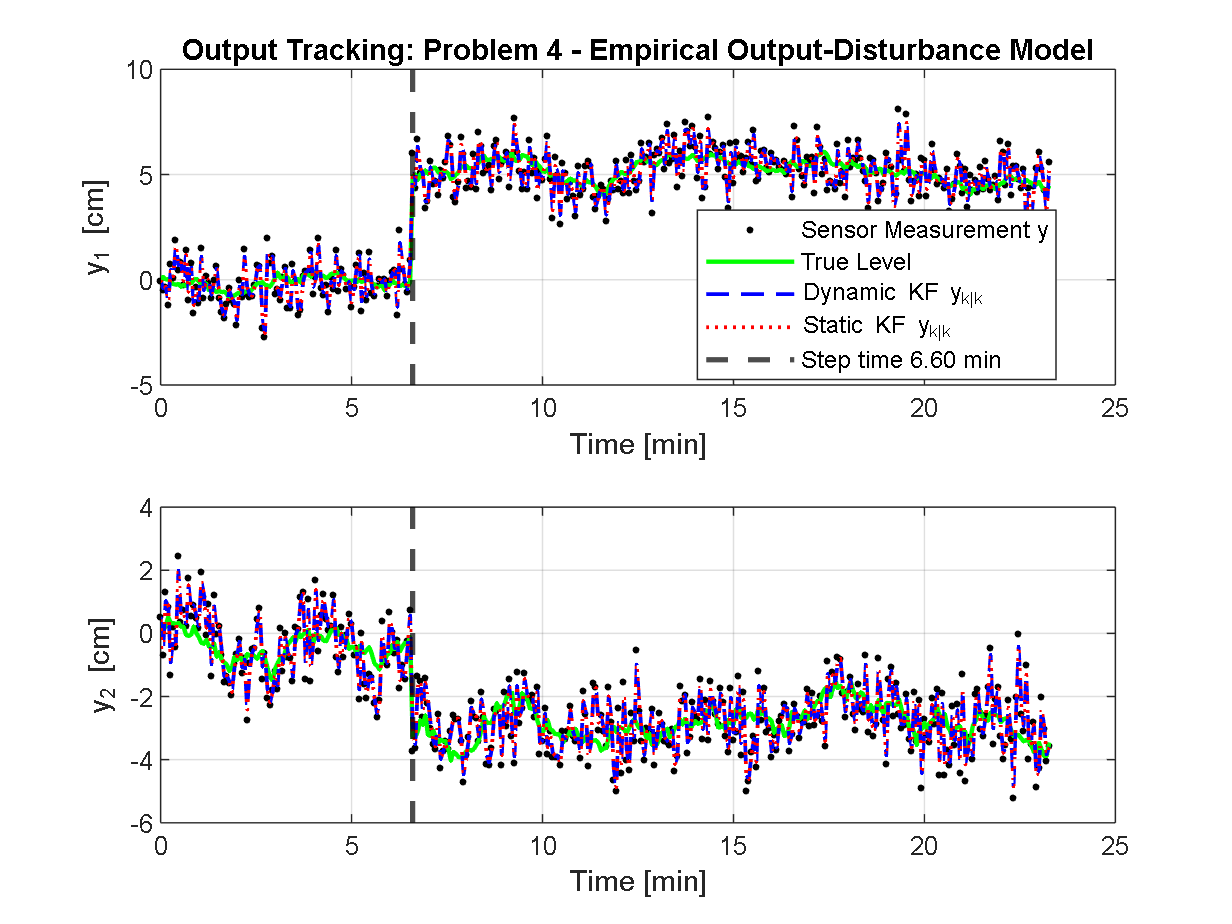

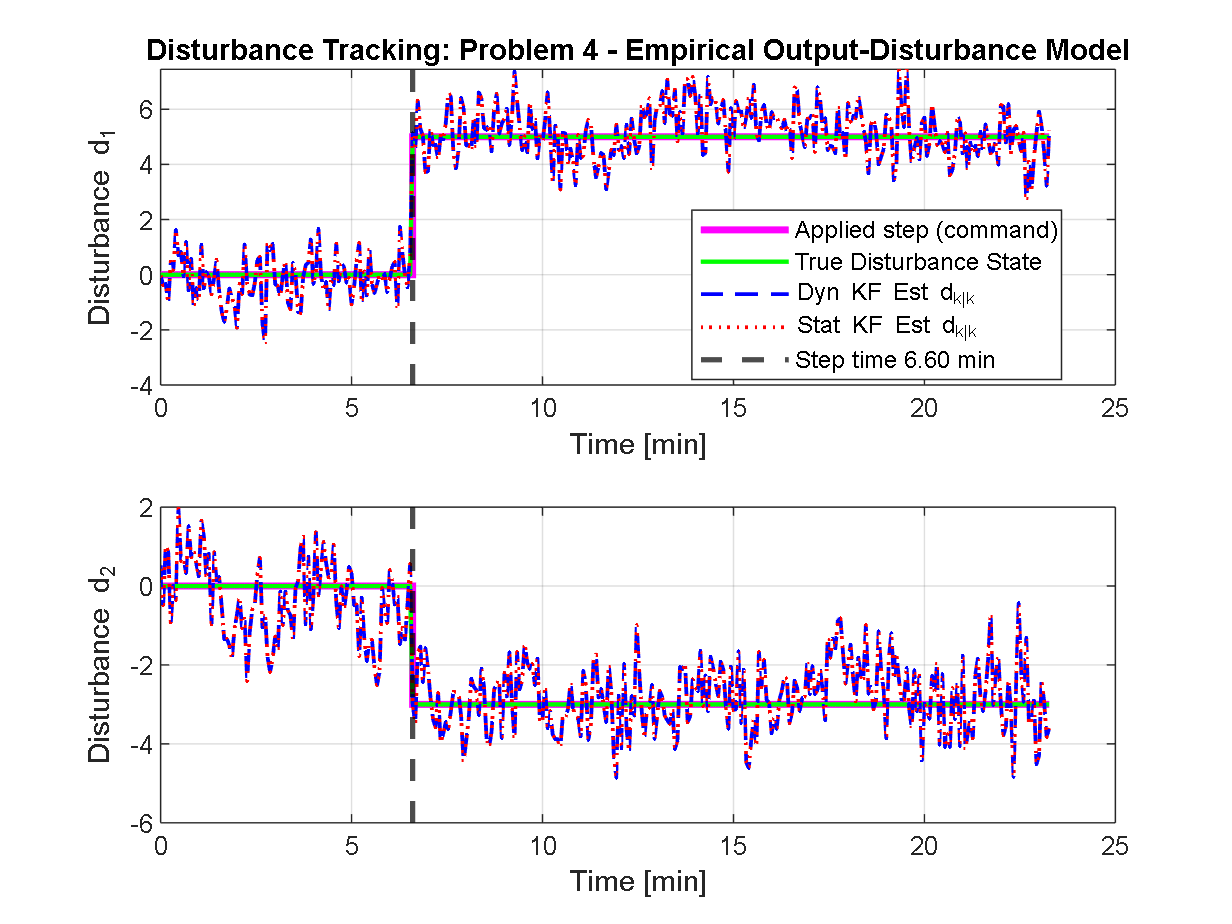

Model: Problem 5 - Physical Brownian Model


Augmented state dimension: 6


Observability rank: 6 / 6


Stationary estimator spectral radius: 0.897547



Performance metrics for Problem 5 - Physical Brownian Model


Output 1 RMSE all: dyn 0.5136, stat 0.5183 | post-step: dyn 0.5261, stat 0.5261


Output 1 final-window mean error: dyn +0.0032, stat +0.0032


Output 2 RMSE all: dyn 0.5152, stat 0.5261 | post-step: dyn 0.5241, stat 0.5241


Output 2 final-window mean error: dyn +0.0120, stat +0.0120


Disturbance 1 RMSE all: dyn 23.5350, stat 23.7306 | post-step: dyn 24.3712, stat 24.3712


Disturbance 1 final-window mean error: dyn -1.1302, stat -1.1302


Disturbance 2 RMSE all: dyn 24.7461, stat 25.1868 | post-step: dyn 25.7437, stat 25.7437


Disturbance 2 final-window mean error: dyn -7.6306, stat -7.6306


Minimum eigenvalue of dynamic posterior P: 8.258e+01


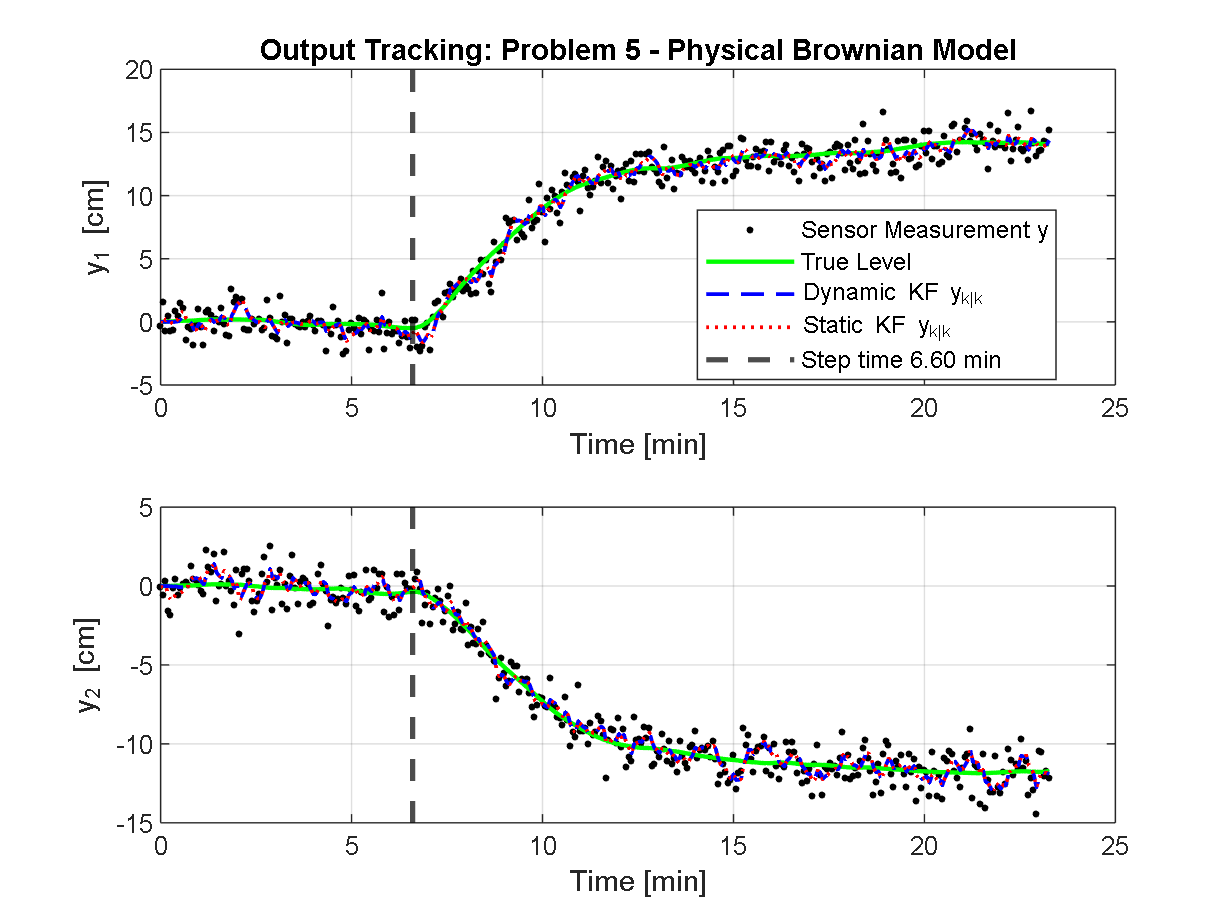

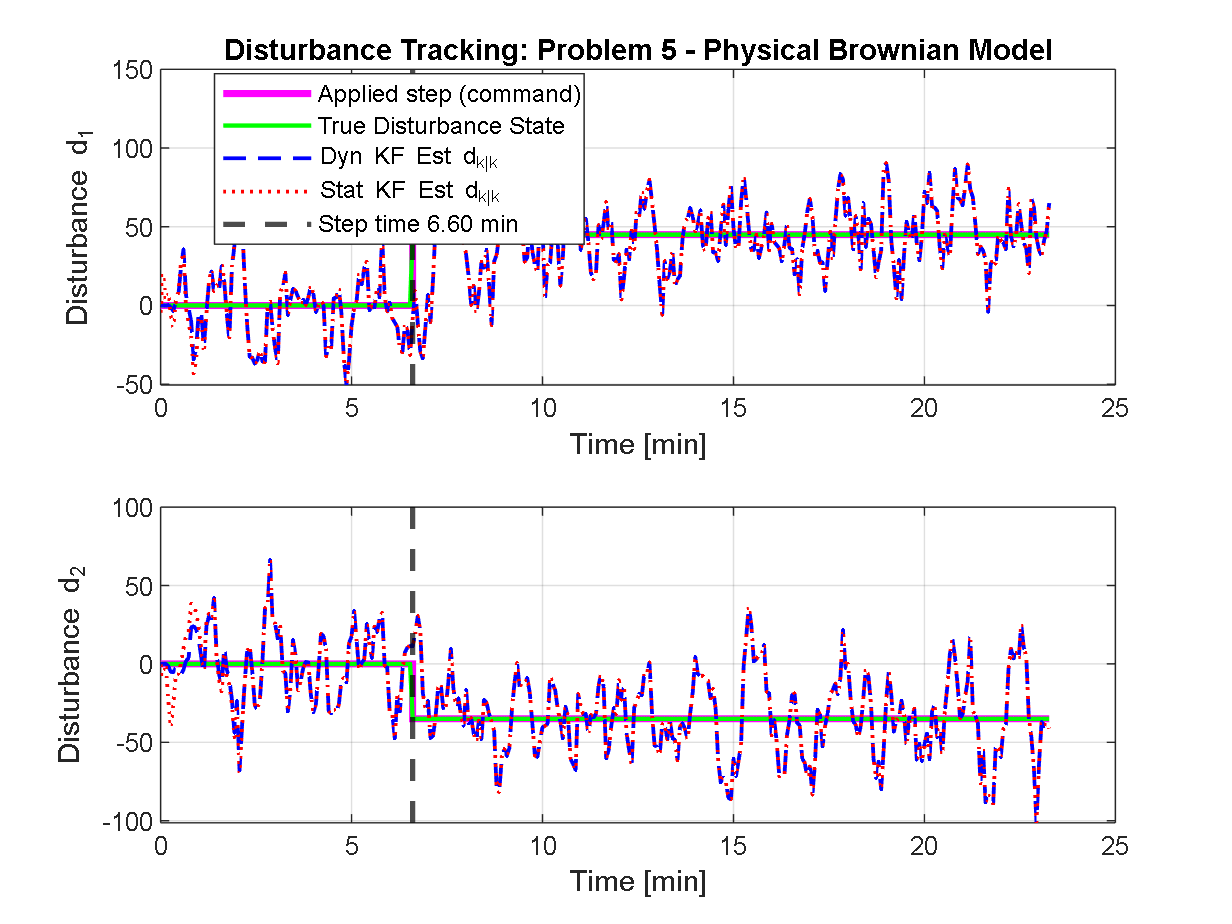

%% Problem 6.3: Offset-Free Kalman Filter Design
% Case: Unmeasured disturbances DO contain step changes.
% Strategy: State augmentation with an output disturbance model.
% Evaluation of both Problem 4 (Empirical) and Problem 5 (Physical) models
clear;
clc;
close all;

%% 1. Compare the two models

for model_idx = 1:2

%% 2. Load and augment the selected model

if model_idx == 1

    % -------------------------------------------------------------
    % MODEL 1: Empirical model from Problem 4
    % Output-disturbance augmentation
    % -------------------------------------------------------------

    model_name = 'Problem 4 - Empirical Output-Disturbance Model';

    load('sysd_stochastic.mat');

    A = Ad_stochastic;
    B = Bd_stochastic;
    C = Cd_stochastic;
    D = Dd_stochastic;
    Ts = Ts_markov;

    nx_plant = size(A, 1);
    nu = size(B, 2);
    ny = size(C, 1);

    % One output-disturbance state is introduced for each output.
    nd = ny;

    % Augmented state:
    % X = [x; d_y]
    %
    % The disturbance model is:
    % d_y(k+1) = d_y(k) + disturbance noise.
    %
    % The output equation is:
    % y(k) = C*x(k) + d_y(k) + D*u(k) + v(k).

    A_aug = [A,                  zeros(nx_plant, nd);
             zeros(nd, nx_plant), eye(nd)];

    B_aug = [B;
             zeros(nd, nu)];

    C_aug = [C, eye(ny)];

    D_aug = D;

    % Process noise enters the plant through B and the disturbance
    % states through an identity matrix.
    G_x = B;

    G_aug = [G_x,                       zeros(nx_plant, nd);
             zeros(nd, size(G_x, 2)),   eye(nd)];

    % Covariance of the plant process noise.
    Q_x = diag([25^2, 25^2]);

    % Covariance of the output-disturbance random walk.
    Q_d = diag([2.0^2, 2.0^2]);

    % Covariance of the augmented process noise.
    Q_aug = blkdiag(Q_x, Q_d);

else

    % -------------------------------------------------------------
    % MODEL 2: Physical Brownian model from Problem 5
    % The disturbance states are already included in the model.
    % -------------------------------------------------------------

    model_name = 'Problem 5 - Physical Brownian Model';

    load('model_prob5_discrete.mat');

    A_aug = A_d_Brownian;
    B_aug = B_d_Brownian;
    C_aug = C_d_Brownian;
    D_aug = D_d_Brownian;
    Ts = Ts_disc;

    % The last two states represent the input disturbances F3 and F4.
    nd = 2;

    % Number of physical plant states, excluding the disturbances.
    nx_plant = size(A_aug, 1) - nd;

    nu = size(B_aug, 2);
    ny = size(C_aug, 1);

    % The Brownian model already contains its disturbance states.
    % Do not augment A_aug, B_aug, or C_aug a second time.
    %
    % The full process-noise covariance is provided by Problem 5.
    G_aug = eye(size(A_aug, 1));
    Q_aug = Q_d_Brownian;

end

%% 3. Check dimensions and model properties

nxa = size(A_aug, 1);

assert(size(A_aug, 2) == nxa, ...
    'A_aug must be square.');

assert(size(B_aug, 1) == nxa, ...
    'Inconsistent dimensions between A_aug and B_aug.');

assert(size(C_aug, 2) == nxa, ...
    'Inconsistent dimensions between A_aug and C_aug.');

assert(size(G_aug, 1) == nxa, ...
    'Inconsistent dimensions between A_aug and G_aug.');

assert(all(size(Q_aug) == [size(G_aug, 2), size(G_aug, 2)]), ...
    'Q_aug has inconsistent dimensions.');

assert(all(size(D_aug) == [ny, nu]), ...
    'D_aug has inconsistent dimensions.');

% Ensure numerical symmetry of the covariance matrix.
Q_aug = (Q_aug + Q_aug') / 2;

R = 1.0^2 * eye(ny);

% S_aug represents the cross-covariance between process and
% measurement noise. Here, the two noise sources are independent.
S_aug = zeros(size(G_aug, 2), ny);

% Check positive semidefiniteness of the process-noise covariance.
if min(eig(Q_aug)) < -1e-8
    error('Q_aug is not positive semidefinite for %s.', model_name);
end

% Check observability of the augmented estimation model.
Obs_aug = obsv(A_aug, C_aug);
observability_rank = rank(Obs_aug);

fprintf('\n====================================================\n');
fprintf('Model: %s\n', model_name);
fprintf('Augmented state dimension: %d\n', nxa);
fprintf('Observability rank: %d / %d\n', ...
    observability_rank, nxa);
fprintf('====================================================\n');

if observability_rank < nxa
    warning(['The augmented model is not fully observable. ', ...
             'Check whether all disturbance states can be estimated.']);
end

%% 4. Design the stationary Kalman filter using the DARE

% Initial estimate and error covariance.
X_bar0 = zeros(nxa, 1);
P0_aug = 100 * eye(nxa);

% Solve the dual discrete algebraic Riccati equation.
%
% The generalized DARE uses:
% A = A_aug', B = C_aug',
% Q = G_aug*Q_aug*G_aug', R = R,
% S = G_aug*S_aug.
%
% P_stat is the stationary prior estimation-error covariance.

Q_state = G_aug * Q_aug * G_aug';

[P_stat, ~, ~] = dare( ...
    A_aug', C_aug', Q_state, R, G_aug * S_aug);

P_stat = (P_stat + P_stat') / 2;

% Innovation covariance at steady state.
Re_stat = C_aug * P_stat * C_aug' + R;

% Stationary Kalman gains.
Kfx_stat = (P_stat * C_aug') / Re_stat;
Kfw_stat = S_aug / Re_stat;

% Check the stability of the stationary estimator error dynamics.
A_est = A_aug - ...
    (A_aug * Kfx_stat + G_aug * Kfw_stat) * C_aug;

rho_est = max(abs(eig(A_est)));

fprintf('Stationary estimator spectral radius: %.6f\n', rho_est);

if rho_est >= 1
    warning(['The stationary estimator error dynamics are not ', ...
             'asymptotically stable for %s.'], model_name);
end

%% 5. Simulation setup

% Use the same random seed for reproducibility.
rng(42);

N_sim = 350;      % Slightly longer horizon so Tank 3->1 hydraulics settle completely
k_step = 100;

time_vec = (0:N_sim-1) * Ts;
t_step_min = time_vec(k_step)/60; % step time, expressed in minutes

% Input signal: zero input for this disturbance-estimation test.
u = zeros(nu, N_sim);

% Define physically meaningful step magnitudes according to the disturbance coordinates:
% - Model 1: Output disturbance in tank level [cm] -> [5; -3] cm
% - Model 2: Input flow disturbance in F3, F4 [cm^3/s] -> [45; -35] cm^3/s
if model_idx == 1
    step_val = [5; -3];
else
    step_val = [45; -35];
end

d_step = zeros(nd, N_sim);
d_step(:, k_step:end) = repmat(step_val, 1, N_sim - k_step + 1);

%% 6. Generate process and measurement noise

% Extract plant-only covariance so the true plant experiences physical process 
% noise while the true disturbance states undergo a clean deterministic step jump.
Q_plant_only = Q_aug;
if model_idx == 1
    % Zero out the random-walk excitation in the true disturbance generator
    Q_plant_only(end-nd+1:end, end-nd+1:end) = 0;
else
    % Keep physical noise on tanks 1..4, but keep true F3/F4 step constant after jump
    Q_plant_only(nx_plant+1:end, :) = 0;
    Q_plant_only(:, nx_plant+1:end) = 0;
end

[Vq, Dq] = eig((Q_plant_only + Q_plant_only')/2);
lambda_q = max(real(diag(Dq)), 0);
L_q = Vq * diag(sqrt(lambda_q));
L_r = chol(R, 'lower');

w_true = L_q * randn(size(Q_aug, 1), N_sim);
v_true = L_r * randn(ny, N_sim);

%% 7. Simulate the TRUE augmented system

X_true = zeros(nxa, N_sim);
y_meas = zeros(ny, N_sim);

for k = 1:N_sim

    % Apply the one-time step jump to the disturbance states at k_step
    if k == k_step
        X_true(nx_plant+1:end, k) = X_true(nx_plant+1:end, k) + step_val;
    end

    % Measurement equation of the complete augmented model
    y_meas(:, k) = C_aug * X_true(:, k) ...
                 + D_aug * u(:, k) ...
                 + v_true(:, k);

    % State transition to the next sample
    if k < N_sim
        X_true(:, k+1) = A_aug * X_true(:, k) ...
                       + B_aug * u(:, k) ...
                       + G_aug * w_true(:, k);
    end

end

% Noise-free output generated by the true augmented state
y_true_clean = C_aug * X_true + D_aug * u;

% True disturbance states used for comparison with their estimates
d_true = X_true(nx_plant+1:end, :);

%% 8. Apply the time-varying Kalman filter

% Implement the lecture's predict/update equations directly here, so the
% result does not depend on external helper functions.
% Measurement update: e=y-C*x_pred-D*u, Omega=C*P_pred*C'+R,
% K=P_pred*C'/Omega, x_filt=x_pred+K*e.
% Prediction: x_pred+=A*x_filt+B*u, P_pred+=A*P_filt*A'+G*Q*G'.
% S_aug=0, so process and measurement noises are uncorrelated.
X_hat_dyn = zeros(nxa, N_sim);
X_pred_dyn = X_bar0;
P_pred_dyn = P0_aug;
P_dyn_history = zeros(nxa, nxa, N_sim);
innovation_dyn = zeros(ny, N_sim);

for k = 1:N_sim
    e_k = y_meas(:,k) - C_aug*X_pred_dyn - D_aug*u(:,k);
    Omega_k = C_aug*P_pred_dyn*C_aug' + R;
    K_k = (P_pred_dyn*C_aug') / Omega_k;

    X_f_dyn = X_pred_dyn + K_k*e_k;
    % Joseph form improves numerical symmetry/positive-semidefinite behavior.
    I_KC = eye(nxa) - K_k*C_aug;
    P_f_dyn = I_KC*P_pred_dyn*I_KC' + K_k*R*K_k';
    P_f_dyn = (P_f_dyn + P_f_dyn')/2;

    X_hat_dyn(:,k) = X_f_dyn;
    P_dyn_history(:,:,k) = P_f_dyn;
    innovation_dyn(:,k) = e_k;

    if k < N_sim
        X_pred_dyn = A_aug*X_f_dyn + B_aug*u(:,k);
        P_pred_dyn = A_aug*P_f_dyn*A_aug' + G_aug*Q_aug*G_aug';
        P_pred_dyn = (P_pred_dyn + P_pred_dyn')/2;
    end
end

%% 9. Apply the stationary Kalman filter

% The stationary filter uses the constant gain computed from the DARE.
% Since S_aug=0, Kfw_stat=0 and the update reduces to x_f=x_pred+K*e.
X_hat_stat = zeros(nxa, N_sim);
X_pred_stat = X_bar0;
innovation_stat = zeros(ny, N_sim);

for k = 1:N_sim
    e_k = y_meas(:,k) - C_aug*X_pred_stat - D_aug*u(:,k);
    X_f_stat = X_pred_stat + Kfx_stat*e_k;
    innovation_stat(:,k) = e_k;
    X_hat_stat(:,k) = X_f_stat;

    if k < N_sim
        X_pred_stat = A_aug*X_f_stat + B_aug*u(:,k);
    end
end

%% 10. Calculate estimated outputs and disturbances

% Reconstruct the estimated outputs using the augmented output model.
y_hat_dyn = C_aug * X_hat_dyn + D_aug * u;
y_hat_stat = C_aug * X_hat_stat + D_aug * u;

% Extract the estimated disturbance states.
d_hat_dyn = X_hat_dyn(nx_plant+1:end, :);
d_hat_stat = X_hat_stat(nx_plant+1:end, :);

%% 11. Calculate performance metrics

% Compare estimates with the noise-free output and actual disturbance states.
rmse_y_dyn = sqrt(mean((y_true_clean - y_hat_dyn).^2, 2));
rmse_y_stat = sqrt(mean((y_true_clean - y_hat_stat).^2, 2));
rmse_d_dyn = sqrt(mean((d_true - d_hat_dyn).^2, 2));
rmse_d_stat = sqrt(mean((d_true - d_hat_stat).^2, 2));

% Post-step metrics exclude the pre-step transient. These are more relevant
% to the requirement that a step disturbance is estimated without offset.
idx_post = k_step:N_sim;
rmse_y_dyn_post = sqrt(mean((y_true_clean(:,idx_post) - y_hat_dyn(:,idx_post)).^2, 2));
rmse_y_stat_post = sqrt(mean((y_true_clean(:,idx_post) - y_hat_stat(:,idx_post)).^2, 2));
rmse_d_dyn_post = sqrt(mean((d_true(:,idx_post) - d_hat_dyn(:,idx_post)).^2, 2));
rmse_d_stat_post = sqrt(mean((d_true(:,idx_post) - d_hat_stat(:,idx_post)).^2, 2));

% Mean estimation error over the final 20 samples is a simple residual-bias
% diagnostic. A single finite noisy run is evidence, not a proof, of offset-free behavior.
idx_final = max(k_step, N_sim-19):N_sim;
bias_y_dyn = mean(y_true_clean(:,idx_final) - y_hat_dyn(:,idx_final), 2);
bias_y_stat = mean(y_true_clean(:,idx_final) - y_hat_stat(:,idx_final), 2);
bias_d_dyn = mean(d_true(:,idx_final) - d_hat_dyn(:,idx_final), 2);
bias_d_stat = mean(d_true(:,idx_final) - d_hat_stat(:,idx_final), 2);

fprintf('\nPerformance metrics for %s\n', model_name);
for i = 1:ny
    fprintf('Output %d RMSE all: dyn %.4f, stat %.4f | post-step: dyn %.4f, stat %.4f\n', ...
        i, rmse_y_dyn(i), rmse_y_stat(i), rmse_y_dyn_post(i), rmse_y_stat_post(i));
    fprintf('Output %d final-window mean error: dyn %+.4f, stat %+.4f\n', ...
        i, bias_y_dyn(i), bias_y_stat(i));
end
for i = 1:nd
    fprintf('Disturbance %d RMSE all: dyn %.4f, stat %.4f | post-step: dyn %.4f, stat %.4f\n', ...
        i, rmse_d_dyn(i), rmse_d_stat(i), rmse_d_dyn_post(i), rmse_d_stat_post(i));
    fprintf('Disturbance %d final-window mean error: dyn %+.4f, stat %+.4f\n', ...
        i, bias_d_dyn(i), bias_d_stat(i));
end

% Numerical checks for covariance recursion and innovations.
if any(~isfinite(X_hat_dyn(:))) || any(~isfinite(X_hat_stat(:)))
    warning('Non-finite state estimates detected for %s.', model_name);
end
min_eig_P = inf;
for k = 1:N_sim
    min_eig_P = min(min_eig_P, min(eig((P_dyn_history(:,:,k)+P_dyn_history(:,:,k)')/2)));
end
fprintf('Minimum eigenvalue of dynamic posterior P: %.3e\n', min_eig_P);
if min_eig_P < -1e-7
    warning('Dynamic covariance lost positive semidefiniteness for %s.', model_name);
end

%% 12. Figure 1: Output Tracking Performance

figure('Name', sprintf('6.3 Output Tracking - %s', model_name));
for i = 1:ny
    subplot(ny, 1, i);
    plot(time_vec/60, y_meas(i, :), 'k.', ...
        'MarkerSize', 7, 'DisplayName', 'Sensor Measurement y'); hold on;
    plot(time_vec/60, y_true_clean(i, :), 'g-', ...
        'LineWidth', 1.5, 'DisplayName', 'True Level');
    plot(time_vec/60, y_hat_dyn(i, :), 'b--', ...
        'LineWidth', 1.3, 'DisplayName', 'Dynamic KF y_{k|k}');
    plot(time_vec/60, y_hat_stat(i, :), 'r:', ...
        'LineWidth', 1.3, 'DisplayName', 'Static KF y_{k|k}');

    % Explicit step marker: vertical line plus label at the top of each axes.
    xline(t_step_min, 'k--', 'LineWidth', 1.8, ...
        'DisplayName', sprintf('Step time %.2f min', t_step_min));

    ylabel(sprintf('y_%d [cm]', i));
    xlabel('Time [min]');
    grid on;
    if i == 1
        legend('show', 'Interpreter', 'tex', 'Location', 'best');
        title(sprintf('Output Tracking: %s', model_name), 'Interpreter', 'none');
    end
end

%% 13. Figure 2: Disturbance Tracking

figure('Name', sprintf('6.3 Disturbance Tracking - %s', model_name));
for i = 1:nd
    subplot(nd, 1, i);
    stairs(time_vec/60, d_step(i, :), 'm-', ...
        'LineWidth', 2.4, 'DisplayName', 'Applied step (command)'); hold on;
    plot(time_vec/60, d_true(i, :), 'g-', ...
        'LineWidth', 1.5, 'DisplayName', 'True Disturbance State');
    plot(time_vec/60, d_hat_dyn(i, :), 'b--', ...
        'LineWidth', 1.3, 'DisplayName', 'Dyn KF Est d_{k|k}');
    plot(time_vec/60, d_hat_stat(i, :), 'r:', ...
        'LineWidth', 1.3, 'DisplayName', 'Stat KF Est d_{k|k}');
    xline(t_step_min, 'k--', 'LineWidth', 1.8, ...
        'DisplayName', sprintf('Step time %.2f min', t_step_min));

    ylabel(sprintf('Disturbance d_%d', i));
    xlabel('Time [min]');
    grid on;
    if i == 1
        legend('show', 'Interpreter', 'tex', 'Location', 'best');
        title(sprintf('Disturbance Tracking: %s', model_name), 'Interpreter', 'none');
    end
end

end


%% END OF PROBLEM 6.3 